# KL distance plots

load(fullfile(get_data_root(),'CompiledData','KLdistance.mat'))

animalID = [65622,63383,67330,67456,66922,65588,67324,67141];
animals = length(animalID);
gen = {'Control','Experimental'};
trials = 25;
session = 6;
day = 1:6;
spatial_bin = 100^2;
colors = {'#284B5E','#BC554C'};
control = [1,2,3,4];
experimental = [5,6,7,8];


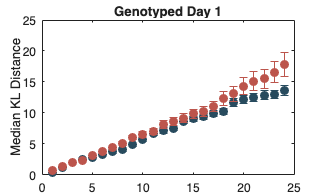

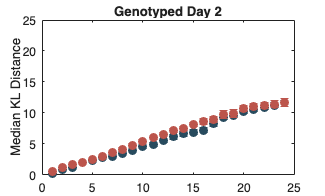

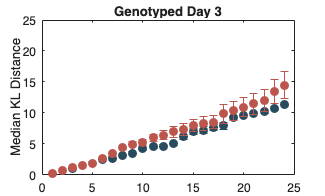

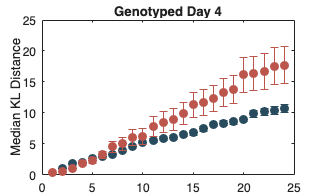

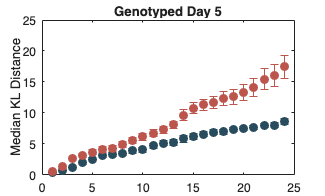

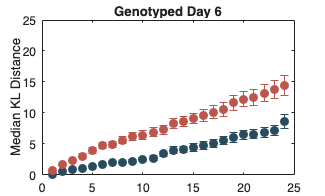

cumsum_days = nan(2,24*6);
cumsum_errors = nan(2,24*6);
grouped_mat = nan(animals,24);
for s = 1:session
    for a = 1:animals
        % arrays = median_population{s,a};
        arrays = median(all_cumsum{s,a});
        if isempty(arrays)

            grouped_mat(a,:) = nan(1,24);
        else
            grouped_mat(a,:) = arrays;
        end

    end

    name = sprintf('Genotyped Day %d',s);

    avr_cont = mean(grouped_mat(control,:),'omitnan');
    avr_exp = mean(grouped_mat(experimental,:),'omitnan');

    error_cont = SE(grouped_mat(control,:));
    error_exp = SE(grouped_mat(experimental,:));

    figure
    e = errorbar(avr_cont,error_cont,'o',"MarkerFaceColor",colors{1},"MarkerEdgeColor",colors{1});
    e.Color = colors{1};
    hold on
    k = errorbar(avr_exp,error_exp,'o',"MarkerFaceColor",colors{2},"MarkerEdgeColor",colors{2});
    k.Color = colors{2};
    ylim([0 25])
    yticks(0:5:25)
    ylabel('Median KL Distance')
    title(name)

    % save_figure(set_path{occ_correct},sprintf('Summary Genotyped Day %d',s))
    % % close;

    if s == 1
        cumsum_days(:,1:24) = [avr_cont;avr_exp];
        cumsum_errors(:,1:24) = [error_cont;error_exp];
    else
        index = 24*(s-1);
        multiplier = cumsum_days(:,index);
        distance_continued = [avr_cont;avr_exp] + multiplier;
        cumsum_days(:,index+1:index+24) = distance_continued;

        % multiplier_error = cumsum_errors(:,index);
        % errors_continued = [error_cont;error_exp] + multiplier_error;
        errors_continued = [error_cont;error_exp];                          % Think this is correct?
        cumsum_errors(:,index+1:index+24) = errors_continued;

    end

end

## Cumulative continued

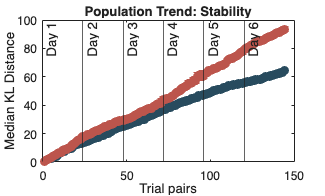

figure
e = errorbar(cumsum_days(1,:),cumsum_errors(1,:),'o',"MarkerFaceColor",colors{1},"MarkerEdgeColor",colors{1});
e.Color = colors{1};
hold on
k = errorbar(cumsum_days(2,:),cumsum_errors(2,:),'o',"MarkerFaceColor",colors{2},"MarkerEdgeColor",colors{2});
k.Color = colors{2};
xline([0,24,48,72,96,120],'-',{'Day 1','Day 2','Day 3','Day 4','Day 5','Day 6'});
xlabel('Trial pairs')
ylabel('Median KL Distance')
title('Population Trend: Stability')


% save_figure(set_path{occ_correct},'Summary full experiment')


## Statistics

% Flatten all data into a table:
all_values = []; group = []; animal_mat = []; session_mat = [];
for a = 1:animals
    for s = 1:6
        data = all_cumsum{s,a};  
        nCells = size(data,1);
        m_vals = median(data,2);  

        all_values = [all_values; m_vals];
        group = [group; repmat(a > 4, nCells, 1)];  % 0 for ctrl, 1 for exp
        animal_mat = [animal_mat; repmat(a, nCells, 1)];
        session_mat = [session_mat; repmat(s, nCells, 1)];
    end
end

T = table(all_values, group, animal_mat, session_mat,'VariableNames', {'KL','Group','Animal','Session'});

% LMM: random intercept per animal
lme = fitlme(T, 'KL ~ Group + (1|Animal)');
disp(lme);


Linear mixed-effects model fit by ML

Model information:
    Number of observations            1201
    Fixed effects coefficients           2
    Random effects coefficients          8
    Covariance parameters                2

Formula:
    KL ~ 1 + Group + (1 | Animal)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    8630.7    8651.1    -4311.4          8622.7  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}        7.8183      0.35551    21.992    1199    2.5129e-90     7.1209    8.5158
    {'Group'      }        1.6733      0.50593    3.3073    1199    0.00096985    0.68067    2.6659

Random effects covariance parameters (95% CIs):
Group: Animal (8 Levels)
    Name1                  Name2                  Type           Estimate    Lower    Up



% I think this is better: NB! intercept is day 1 in matlab syntax
T.Session = categorical(T.Session);
lme = fitlme(T, 'KL ~ Group*Session');
disp(lme)


Linear mixed-effects model fit by ML

Model information:
    Number of observations            1201
    Fixed effects coefficients          12
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    KL ~ 1 + Group*Session

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    8617.4    8683.6    -4295.7          8591.4  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE         tStat       DF      pValue        Lower      Upper 
    {'(Intercept)'    }          8.3041    0.86522      9.5977    1189    4.6318e-21     6.6066    10.002
    {'Group'          }         0.50949     1.2571     0.40527    1189       0.68535     -1.957    2.9759
    {'Session_2'      }        -0.56302      1.165    -0.48327    1189       0.62899    -2.8487    1.7227
    {'Session_3'      }        -0.67422     1.3986    -0.48207

## Slopes

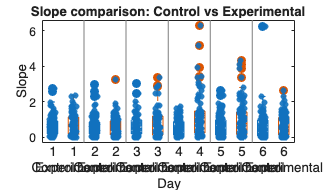

slope = cell(6,2);
p = nan(6,1); 
for s = 1:6

    % control cells
    distances_contr = cell2mat(all_cumsum(s,control)');
    [cell_numb,t] = size(distances_contr);
    x = 1:t;
    for c = 1:cell_numb
        r = polyfit(x, distances_contr(c,:), 1);
        overall_slope = r(1); 
        slope{s,1}(c) = overall_slope;

    end
    ncells(s,1) = cell_numb;
    group_mat{s,1}(:,1) = repmat(s,cell_numb,1);


    % experimental cells
    distances_exp = cell2mat(all_cumsum(s,experimental)');
    [cell_numb,t] = size(distances_exp);

    for c = 1:cell_numb
        r = polyfit(x, distances_exp(c,:), 1);
        overall_slope = r(1); 
        slope{s,2}(c) = overall_slope;

    end
    ncells(s,2) = cell_numb;
    group_mat{s,2}(:,1) = repmat(s,cell_numb,1);

    x1 = slope{s,1};
    x2 = slope{s,2};

    % Wilcoxon rank-sum test (Mann-Whitney U)
    p(s) = ranksum(x1, x2); 
end

contr_cells = cell2mat(slope(:,1)')';
exp_cells = cell2mat(slope(:,2)')';

data = [contr_cells;exp_cells];

% Grouping variables
groups = [cell2mat(group_mat(:,1)); cell2mat(group_mat(:,2))];

type = [repmat({'Control'}, sum(ncells(:,1)), 1);repmat({'Experimental'}, sum(ncells(:,2)), 1)];

figure
boxplot(data, {groups, type}, 'factorseparator', 1,'colors', lines(2), 'symbol', 'o')
ylabel('Slope')
xlabel('Day')
title('Slope comparison: Control vs Experimental')
hold on
g = findgroups(groups, type);   
jit = 0.25*(rand(size(data))-0.5); 
scatter(g + jit, data, 20, 'filled', 'MarkerFaceAlpha', 0.9)


p_val = p

p_val =     0.3173
    0.8982
    0.8395
    0.0005
    0.0072
    0.1377
